Create Neural Networks

sigmaA = [6.5000 2.1651 1.2500; 2.1651 5.1250 2.3816; 1.2500 2.3816 2.3750];
sigmaB = [3.0814 0.4331 -1.4481;0.4331 0.94336 -0.6456;-1.4481 -0.6456 1.2880];
sigmaC = [6.8928 -1.3750 3.1945;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500];

muA = [0; 4; 7];
muB = [10; 5; 5];
muC = [-2; -5; -5];

yA_correct = Gaussian_correct(3,1000, muA, sigmaA);
yB_correct = Gaussian_correct(3,1000, muB, sigmaB);
yC_correct = Gaussian_correct(3,1000, muC, sigmaC);

% (Num^3)-by-3 matrix containing the coordinates for regularily spaced
% points inside of a rectangular volume
x = vol3D([-30 30 -30 30 -30 30],200);

% create dataset and labels
datasets = [yA_correct;yB_correct;yC_correct]';
labels = [zeros(1000,1);ones(1000,1);2*ones(1000,1)]';

% onehotencode labels for response
labels = categorical(labels);
Predictors = datasets;
Response = onehotencode(labels,1);

% train
net = patternnet(5);
net.trainParam.showWindow = false;
[net,tr] = train(net,Predictors ,Response);

% predict on 3d volume
predictions_nn = net(x');
classA_prob = predictions_nn(1,:);
classB_prob = predictions_nn(2,:);
classC_prob = predictions_nn(3,:);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A = find(abs(classA_prob - max(classB_prob,classC_prob)) < espil);
index_B = find(abs(classB_prob - max(classA_prob,classC_prob)) < espil);
index_C = find(abs(classC_prob - max(classA_prob,classB_prob)) < espil);

plot

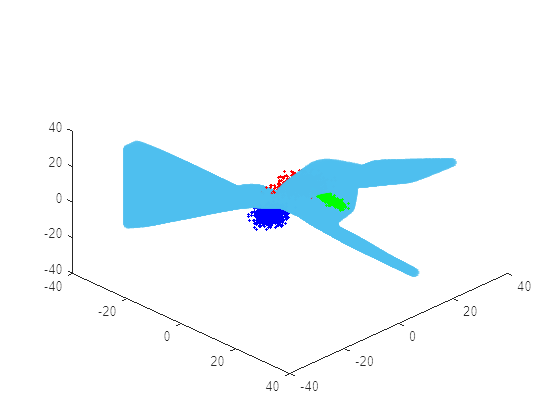

% plot decision boudaries
f1 = figure;
hold on
plot_decision_boundaries_three_classes(x, index_A, index_B, index_C);
plot_dataset(yA_correct, yB_correct, yC_correct );
view(45,45);
hold off

Matlab's computations of errors are incorrect, becuase it included training errors which look good and actually meaningless. The model of course is doing well on the dataset it has already seen.

From the results of the 10 trainings, we can observe that:

1, all inter-class decision boundaries are similar and can decently separate the classes;

2, some boundaries are slightly better than the others;

3, however there are no obvious trends;

4, each time running the program, the boundaries varies.

Therefore, we expect the same situation for the decision boundaries if 100 different neural network training were conducted. However, the neural network decision boundaries would be more correct as increasingly more neurons are added to the neural network’s hidden layer(s).

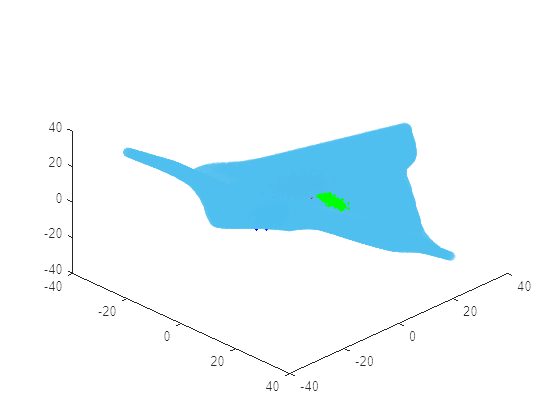

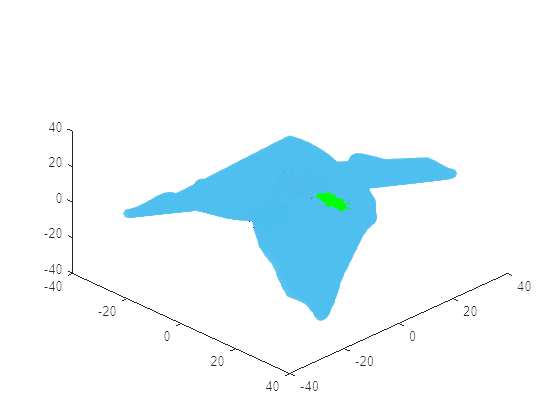

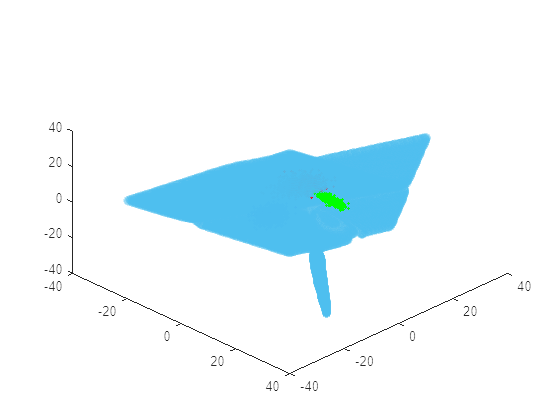

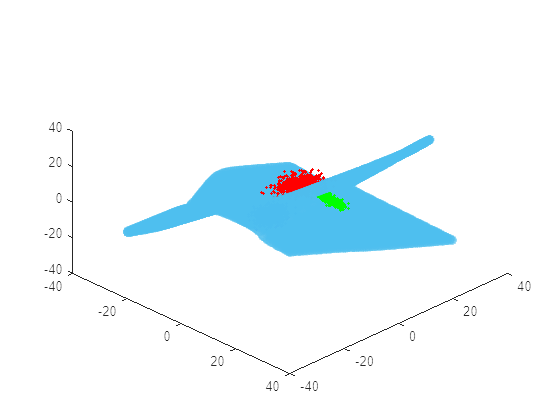

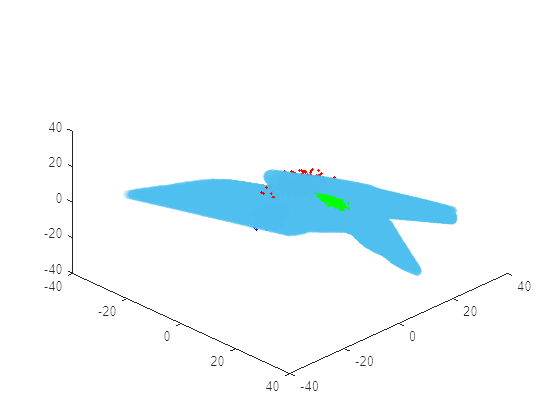

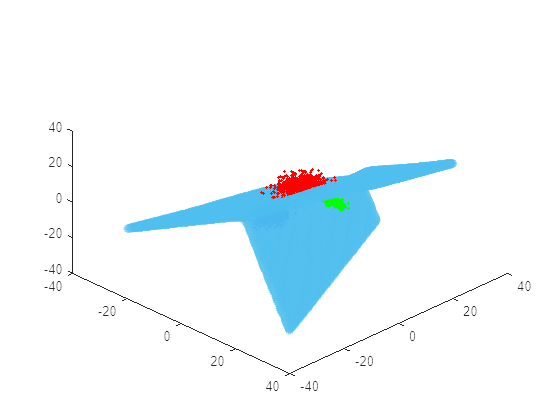

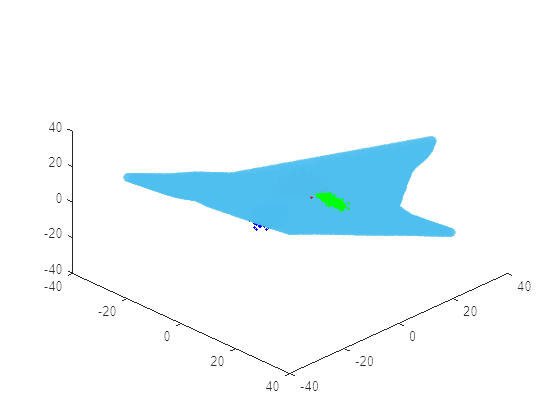

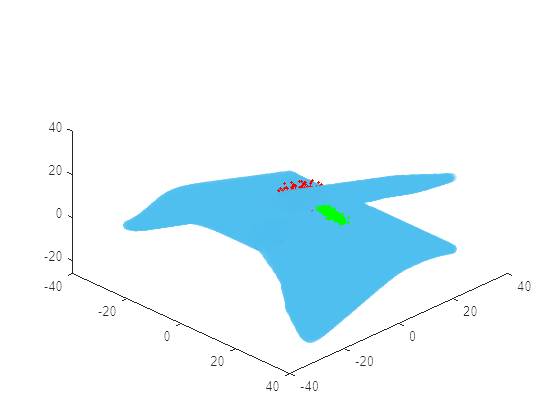

%train net for 10 times
num_times = 10;
train_nn(num_times, net, Predictors ,Response, x, yA_correct, yB_correct, yC_correct);

An NN model cannot be trained to give decision boundaries that are identical to Bayesian decision boundaries, because neural networks do have have infinite amount of information like Bayes classifier. Bayes taking mean and covariance as parameters which are descriptions of the dataset itself and contain information that can extend to infinity, while the neural net needed to be properly tuned and trained on finite number of data. However, nerural networks are universal function approximators and they can potentially produce results like Bayes according to universal approximation theorem if they can get same amount of information like Bayes. However, it is not possible beacuse we do not have infinite computing powers. This case is a proof of the No Free Lunch Theorem.

Last time we tried 3 outliers of class A, with Mahalanobis distances = 10, 50, and 100 for Bayes classifier. Therefore, we perform the same procedure on class A this time and compare the resulting boundaries.

From the resulting plots below, we observe that the outliers notably effect the neural network decision boundaries. Comparing to the Bayesian decision boundaries we did last time, the neural network is also sensative to outliers but decision boundaries are more sensitive to outliers, because Bayesian decision boudaries taking means and covariances as parameters which are very sensitive to outliers and we already observed this in excercise 2. In contrast, neural networks uses sigmoid function which is comparatively less affected by outliers.

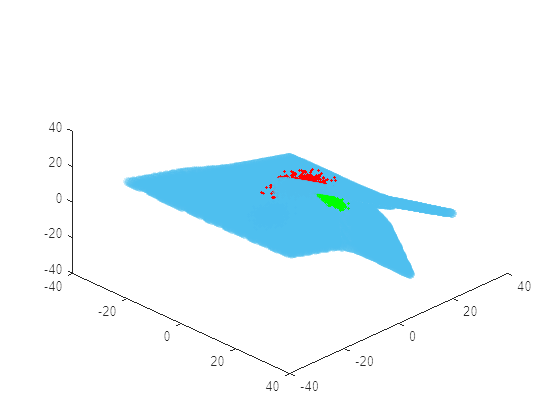

% Case 1: Mahalanobis distance = 10
distance = 10;
inv_sigmaA = inv(sigmaA);
val = (distance^2)/inv_sigmaA(1,1);
val = sqrt(val);
outlier_10 = [val;4;7];
yA_outlier= [yA_correct(1:999,:);outlier_10'];
%new_muA = mean(yA_outlier);
%new_sigmaA = cov(yA_outlier);

datasets = [yA_outlier;yB_correct;yC_correct]';
labels = [zeros(1000,1);ones(1000,1);2*ones(1000,1)]';

% onehotencode labels for response
labels = categorical(labels);
Predictors = datasets;
Response = onehotencode(labels,1);

% train
net = patternnet(5);
net.trainParam.showWindow = false;
[net,tr] = train(net,Predictors ,Response);

% predict on 3d volume
predictions_nn = net(x');
classA_prob = predictions_nn(1,:);
classB_prob = predictions_nn(2,:);
classC_prob = predictions_nn(3,:);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A = find(abs(classA_prob - max(classB_prob,classC_prob)) < espil);
index_B = find(abs(classB_prob - max(classA_prob,classC_prob)) < espil);
index_C = find(abs(classC_prob - max(classA_prob,classB_prob)) < espil);
% plot decision boudaries
f1 = figure;
hold on
plot_decision_boundaries_three_classes(x, index_A, index_B, index_C);
plot_dataset(yA_correct, yB_correct, yC_correct );
view(45,45);
hold off

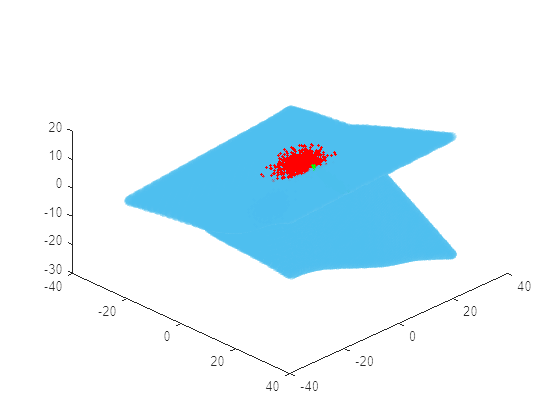

% Case 2: Mahalanobis distance = 50
distance = 50;
inv_sigmaA = inv(sigmaA);
val = (distance^2)/inv_sigmaA(1,1);
val = sqrt(val);
outlier_10 = [val;4;7];
yA_outlier= [yA_correct(1:999,:);outlier_10'];
%new_muA = mean(yA_outlier);
%new_sigmaA = cov(yA_outlier);

datasets = [yA_outlier;yB_correct;yC_correct]';
labels = [zeros(1000,1);ones(1000,1);2*ones(1000,1)]';

% onehotencode labels for response
labels = categorical(labels);
Predictors = datasets;
Response = onehotencode(labels,1);

% train
net = patternnet(5);
net.trainParam.showWindow = false;
[net,tr] = train(net,Predictors ,Response);

% predict on 3d volume
predictions_nn = net(x');
classA_prob = predictions_nn(1,:);
classB_prob = predictions_nn(2,:);
classC_prob = predictions_nn(3,:);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A = find(abs(classA_prob - max(classB_prob,classC_prob)) < espil);
index_B = find(abs(classB_prob - max(classA_prob,classC_prob)) < espil);
index_C = find(abs(classC_prob - max(classA_prob,classB_prob)) < espil);
% plot decision boudaries
f1 = figure;
hold on
plot_decision_boundaries_three_classes(x, index_A, index_B, index_C);
plot_dataset(yA_correct, yB_correct, yC_correct );
view(45,45);
hold off

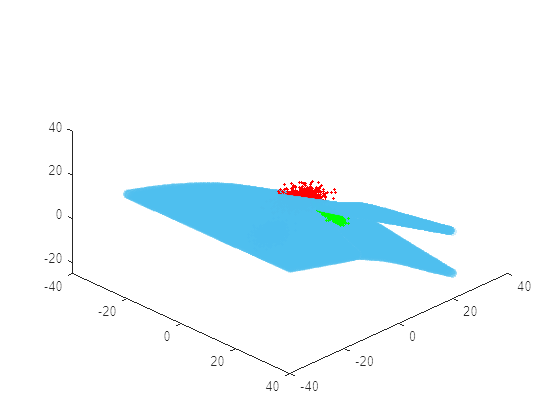

% Case 3: Mahalanobis distance = 100
distance = 100;
inv_sigmaA = inv(sigmaA);
val = (distance^2)/inv_sigmaA(1,1);
val = sqrt(val);
outlier_10 = [val;4;7];
yA_outlier= [yA_correct(1:999,:);outlier_10'];
%new_muA = mean(yA_outlier);
%new_sigmaA = cov(yA_outlier);

datasets = [yA_outlier;yB_correct;yC_correct]';
labels = [zeros(1000,1);ones(1000,1);2*ones(1000,1)]';

% onehotencode labels for response
labels = categorical(labels);
Predictors = datasets;
Response = onehotencode(labels,1);

% train
net = patternnet(5);
net.trainParam.showWindow = false;
[net,tr] = train(net,Predictors ,Response);

% predict on 3d volume
predictions_nn = net(x');
classA_prob = predictions_nn(1,:);
classB_prob = predictions_nn(2,:);
classC_prob = predictions_nn(3,:);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A = find(abs(classA_prob - max(classB_prob,classC_prob)) < espil);
index_B = find(abs(classB_prob - max(classA_prob,classC_prob)) < espil);
index_C = find(abs(classC_prob - max(classA_prob,classB_prob)) < espil);
% plot decision boudaries
f1 = figure;
hold on
plot_decision_boundaries_three_classes(x, index_A, index_B, index_C);
plot_dataset(yA_correct, yB_correct, yC_correct );
view(45,45);
hold off

We can see from the two resulting plots that, when train:validation:test =7:3:90, the boundaries is not accurate as the space for the green class is too large. But it may do better in terms of generalbility when it faces new data as the model cannot just fit training data. For the first case, it can do well on training data but may not perform well for new data as neural network can only perform well on data it has seen and prone to overfitting of training data.

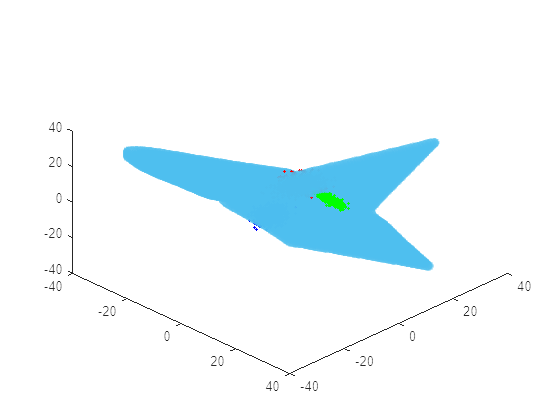

% First situation, training data : validation data : test data = 80:10:10
% create dataset and labels
datasets = [yA_correct;yB_correct;yC_correct]';
labels = [zeros(1000,1);ones(1000,1);2*ones(1000,1)]';

% onehotencode labels for response
labels = categorical(labels);
Predictors = datasets;
Response = onehotencode(labels,1);

% train
net = patternnet(5);
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 10/100;
net.divideParam.testRatio = 10/100;
net.trainParam.showWindow = false;
[net,tr] = train(net,Predictors ,Response);
% predict on 3d volume
predictions_nn = net(x');
classA_prob = predictions_nn(1,:);
classB_prob = predictions_nn(2,:);
classC_prob = predictions_nn(3,:);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A = find(abs(classA_prob - max(classB_prob,classC_prob)) < espil);
index_B = find(abs(classB_prob - max(classA_prob,classC_prob)) < espil);
index_C = find(abs(classC_prob - max(classA_prob,classB_prob)) < espil);
% plot decision boudaries
f1 = figure;
hold on
plot_decision_boundaries_three_classes(x, index_A, index_B, index_C);
plot_dataset(yA_correct, yB_correct, yC_correct );
view(45,45);
hold off

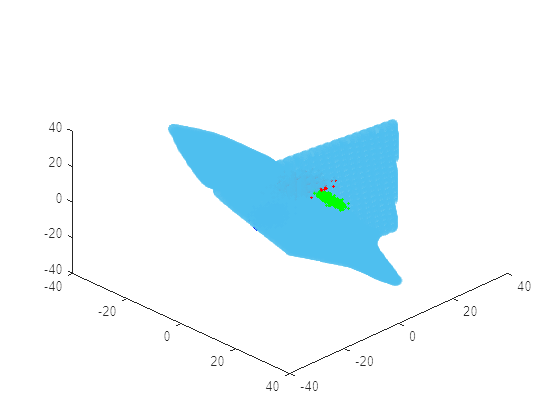

% Second situation, training data : validation data : test data = 7:3:90
% create dataset and labels
datasets = [yA_correct;yB_correct;yC_correct]';
labels = [zeros(1000,1);ones(1000,1);2*ones(1000,1)]';

% onehotencode labels for response
labels = categorical(labels);
Predictors = datasets;
Response = onehotencode(labels,1);

% train
net = patternnet(5);
net.divideParam.trainRatio = 7/100;
net.divideParam.valRatio = 3/100;
net.divideParam.testRatio = 90/100;
net.trainParam.showWindow = false;
[net,tr] = train(net,Predictors ,Response);
% predict on 3d volume
predictions_nn = net(x');
classA_prob = predictions_nn(1,:);
classB_prob = predictions_nn(2,:);
classC_prob = predictions_nn(3,:);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A = find(abs(classA_prob - max(classB_prob,classC_prob)) < espil);
index_B = find(abs(classB_prob - max(classA_prob,classC_prob)) < espil);
index_C = find(abs(classC_prob - max(classA_prob,classB_prob)) < espil);
% plot decision boudaries
f1 = figure;
hold on
plot_decision_boundaries_three_classes(x, index_A, index_B, index_C);
plot_dataset(yA_correct, yB_correct, yC_correct );
view(45,45);
hold off

function x = Gaussian_correct(D,K, mu, sigma)% function for accurate dataset% create 3 classes of dataset 
    data = randn(K,D);
    % singular decomposition of covariance
    [u,s,~] = svd(sigma);
    s = sqrt(s);
    % only use left or right singular vectors
    % use left here to create correlations
    data_correlated = data*s*u' + mu';
    m = mean(data_correlated); % mean of data generated with specified mean
    c = cov(data_correlated); %covarinace of data generated with specified covarinace

    % subtracting mean
    x = data_correlated - m;

    % Whitening transformation
    % Peform eigenvalue/eigenvector decomposition
    [v,d] = eig(c);
    [ d_sorted , idx_sorted ] = sort( diag( d ) , 'descend' );
    w = v(:, idx_sorted);
    x = x * w * diag(1./sqrt(d_sorted));
    x = x*s*u' + mu';
end

function V = vol3D(Vaxis,Num)
% VOL3D Build 3D volume of regular grid points.
%   V = vol3D(Vaxis,Num) returns a (Num^3)-by-3 matrix containing the
%   coordinates for regularily spaced points inside of a rectangular
%   volume. The points are listed row-wise in V: the x-coordinates of
%   all points are V(:,1). Similarily, the y-coordinates are V(:,2) and
%   the z-coordinates are V(:,3).
%
%   Vaxis is a 6-element vector which defines the rectangular volume. Each
%   pair of elements define the minimum and maximum extent of the volume
%   along an axis. For example, a 4x6x8 volume centred on the origin would
%   be defined with Vaxis = [-2 2 -3 3 -4 4]
%   
%   Num is a scalar. It is the number of points to generate along any axis.
%   The total number of points generated is Num^3.

NV = Num;

if length(Vaxis) == 2
    Vaxis = [Vaxis Vaxis Vaxis];
end

min_a = Vaxis(1);
max_a = Vaxis(2);
res = (max_a-min_a)/(NV-1);

r = min_a:res:max_a;
r = r(:);

rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';

x = zeros(3,length(rz)^3);
k =1;
j = 1;
for i = 1:length(rz):length(x)
    x(3,(i-1)+(1:length(rz)))= rz;
    x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
    x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
    k = k+1;
    if k > length(rz)
        k =1;
        j = j +1;
    end
end
x = x';
V = x;
end

% function to plot decision boudaries
%'MarkerEdgeColor',[0.3010 0.7450 0.9330],"MarkerFaceColor",[0.3010 0.7450 0.9330],
function plot_decision_boundaries_three_classes(x, indexA, indexB, indexC)
    scatter3(x(indexA,1),x(indexA,2),x(indexA,3),'MarkerEdgeColor',[0.3010 0.7450 0.9330],"MarkerFaceColor",[0.3010 0.7450 0.9330],'MarkerEdgeAlpha',0.25,'MarkerFaceAlpha',0.25);
    scatter3(x(indexB,1),x(indexB,2),x(indexB,3),'MarkerEdgeColor',[0.3010 0.7450 0.9330],"MarkerFaceColor",[0.3010 0.7450 0.9330],'MarkerEdgeAlpha',0.25,'MarkerFaceAlpha',0.25);
    scatter3(x(indexC,1),x(indexC,2),x(indexC,3),'MarkerEdgeColor',[0.3010 0.7450 0.9330],"MarkerFaceColor",[0.3010 0.7450 0.9330],'MarkerEdgeAlpha',0.25,'MarkerFaceAlpha',0.25);
end

% function to plot dataset
function plot_dataset(ClassA, ClassB, ClassC)
    plot3(ClassA(:,1),ClassA(:,2),ClassA(:,3),'red.');
    plot3(ClassB(:,1),ClassB(:,2),ClassB(:,3),'green.');
    plot3(ClassC(:,1),ClassC(:,2),ClassC(:,3),'blue.');
end

% functions to train neural nets
function train_nn(Epoch, nn, Predictors, Response, x, yA, yB, yC)
    net = init(nn);
    net.trainParam.showWindow = false;
    [trained_net,tr] = train(net,Predictors,Response);
    % train multiple times for
    for i=1:Epoch
        trained_net = init(trained_net);
        trained_net.trainParam.showWindow = false;
        [trained_net,tr] = train(trained_net,Predictors,Response);
        predictions = trained_net(x');
        classA_prob10 = predictions(1,:);
        classB_prob10 = predictions(2,:);
        classC_prob10 = predictions(3,:);
        
        % find index of results (decision boudaries in space of x)
        espil = 0.1;
        index_A10 = find(abs(classA_prob10 - max(classB_prob10,classC_prob10)) < espil);
        index_B10 = find(abs(classB_prob10 - max(classA_prob10,classC_prob10)) < espil);
        index_C10 = find(abs(classC_prob10 - max(classA_prob10,classB_prob10)) < espil);
        
        % plot decision boudaries
        f2 = figure;
        hold on
        plot_decision_boundaries_three_classes(x, index_A10, index_B10, index_C10);
        plot_dataset(yA, yB, yC);
        view(45,45);
        hold off
    end
end